clc
clear
% load('wheat_line_travelling_wind_rectangular.mat');
% load('wheat_line_travelling_wind_rectangular_large_freq');
% load('wheat_line_travelling_wind_rectangular_alpha_50_beta_0.mat');
load('wheat_line_travelling_wind_rectangular_alpha_50_beta_0_large_freq.mat');

natural_freq = 16 / (2*pi);  % Natural frequency
[~, nat_freq_order] = min(abs(wind_frequency_list - natural_freq));  % Find the index of the closest frequency

natural_freq2 = 2*16 / (2*pi);  % Natural frequency
[~, nat_freq2_order] = min(abs(wind_frequency_list - natural_freq2));  % Find the index of the closest frequency

% clf
% figure(1)
% for i=1:size(force_frequency_list,2)
%     plot(result(i).y.Time,squeeze(result(i).y.Data(1,1,:)),'DisplayName',['freq=' force_frequency_list(i) ' rad/s'])
%     hold on
% end
% legend
% xlabel('force frequency (rad/s)')
% ylabel('y (m)')
% title('Occilation plot')

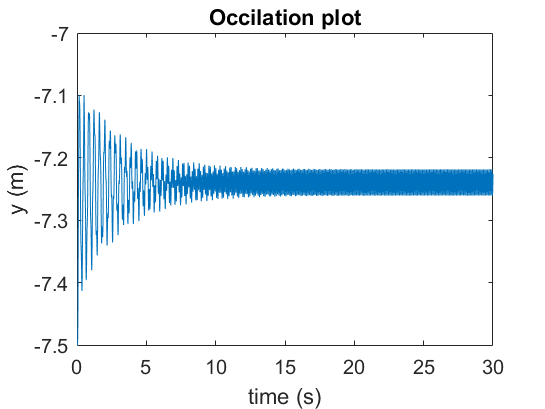

clf
figure(1)
% wind_freq_order = 50;
% wind_freq_order = nat_freq2_order;
wind_freq_order = 2;
wind_freq = wind_frequency_list(wind_freq_order);
wheat_order = 2;
plot(result(wind_freq_order).y.Time,squeeze(result(wind_freq_order).y.Data(wheat_order,1,:)))
xlabel('time (s)')
ylabel('y (m)')
title('Occilation plot')

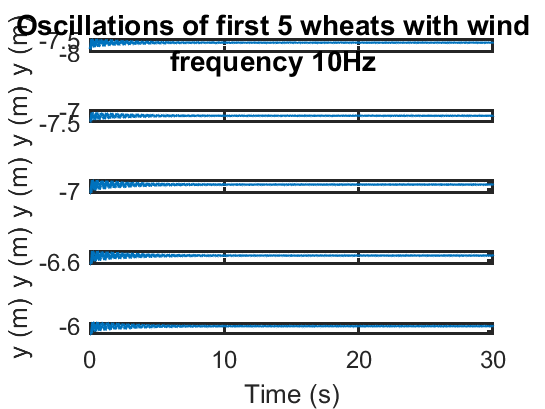

% Clear previous figures
clf

% Create a new figure
fig = figure(1);
set(fig, 'Color', 'w'); % Set background color to white

wind_freq = wind_frequency_list(wind_freq_order);

ax = [];

% Loop over first 5 wheats
for wheat_order = 1:5
    % Create a subplot for each wheat
    ax(wheat_order) = subplot(5, 1, wheat_order);
    
    % Plot the oscillation data
    plot(result(wind_freq_order).y.Time, squeeze(result(wind_freq_order).y.Data(wheat_order,1,:)), 'LineWidth', 1.5);
    
    % Set the x and y labels
%     xlabel('Time (s)');
    ylabel('y (m)');
    
    % Set the axis line width
    set(gca, 'LineWidth', 1.5, 'FontSize', 12);
    
    % Enable grid
    grid off
end

% Link the x-axis of all subplots
linkaxes(ax, 'x');

% Hide the x-tick labels of all but the bottom subplot
set(ax(1:end-1), 'XTickLabel', []);

% Add x-label to the bottom subplot
xlabel(ax(end), 'Time (s)');

% Set a common title for all the subplots
% suptitle('Oscillations of First 5 Wheats under specified wind frequency');

% Adjust the subplot spacing
% Add a common title for all subplots using a text annotation
annotation('textbox', [0 0.9 1 0.1], ...
    'String', ['Oscillations of first 5 wheats with wind frequency ' num2str(wind_freq) 'Hz'], ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 14, ...
    'FontWeight', 'bold');

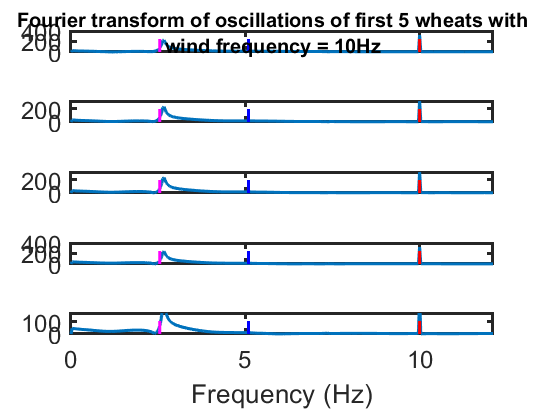

% Clear previous figures
clf

% Create a new figure
fig = figure(1);
set(fig, 'Color', 'w'); % Set background color to white

wind_freq = wind_frequency_list(wind_freq_order);
natural_freq = 16/(2*pi);
twice_natural_freq = 2 * natural_freq;

% Calculate the frequency axis for FFT
N = length(result(wind_freq_order).y.Time);
f = (0:N-1)/(N*0.001); % Frequency in Hz

ax = []; % Initialize a vector to store the axes handles

% Loop over first 5 wheats
for wheat_order = 1:5
    % Create a subplot for each wheat
    ax(wheat_order) = subplot(5, 1, wheat_order);
    
    % Perform FFT and plot the magnitude
    y_fft = abs(fft(squeeze(result(wind_freq_order).y.Data(wheat_order,1,:))));
    y_fft(1) = 0;
    plot(f, y_fft, 'LineWidth', 1.5);
    
    % Mark the natural frequency, twice natural frequency and wind frequency
    line([natural_freq natural_freq], get(gca, 'ylim'), 'Color', 'm', 'LineStyle', '--', 'LineWidth', 1.5, 'DisplayName', 'Natural Frequency');
    line([twice_natural_freq twice_natural_freq], get(gca, 'ylim'), 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1.5, 'DisplayName', 'Twice Natural Frequency');
    line([wind_freq wind_freq], get(gca, 'ylim'), 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1.5, 'DisplayName', 'Wind Frequency');
    
    % Set the axis line width
    set(gca, 'LineWidth', 1.5, 'FontSize', 12);
    
    % Set x-axis limits
    xlim([0, 12]);
    
    % Enable grid
    grid off
end

% Link the x-axis of all subplots
linkaxes(ax, 'x');

% Hide the x-tick labels of all but the bottom subplot
set(ax(1:end-1), 'XTickLabel', []);

% Add x-label to the bottom subplot
xlabel(ax(end), 'Frequency (Hz)');

% Get the position of the last subplot (bottom subplot)
bottom_subplot_position = get(ax(end), 'Position');

% Calculate the new height for each subplot
subplot_height = bottom_subplot_position(4);

% % Loop over all subplots and adjust their positions
% for i = 1:length(ax)
%     % Get the current position
%     subplot_position = get(ax(i), 'Position');
%     
%     % Adjust the bottom y-position and the height
%     subplot_position(2) = bottom_subplot_position(2) + (i-1) * subplot_height;
%     subplot_position(4) = subplot_height;
%     
%     % Set the new position
%     set(ax(i), 'Position', subplot_position);
% end

% Add a common title for all subplots using a text annotation
annotation('textbox', [0 0.9 1 0.1], ...
    'String', ['Fourier transform of oscillations of first 5 wheats with wind frequency = ' num2str(wind_freq) 'Hz' ], ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 10, ...
    'FontWeight', 'bold');

% Add a legend for the colored lines
% legend('Location', 'southoutside', 'Orientation', 'horizontal');

% Create an invisible axes that spans the whole figure
h = axes('Visible', 'off', 'Position', [0, 0, 1, 1], 'XLim', [0, 1], 'YLim', [0, 1]);


% Add a y-label to the axes
% ylabel(h, 'Magnitude', 'FontSize', 12, 'Position', [0.02, 0.5, 0], 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

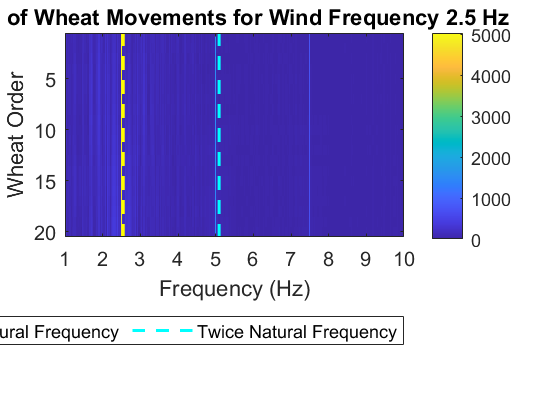

% Clear previous figures
clf

% Create a new figure
fig = figure(1);
set(fig, 'Color', 'w'); % Set background color to white

% wind_freq_order = 50;
wind_freq = wind_frequency_list(wind_freq_order);
natural_freq = 16/(2*pi);
twice_natural_freq = 2 * natural_freq;

% Calculate the frequency axis for FFT
N = length(result(wind_freq_order).y.Time);
f = (0:N-1)/(N*0.001); % Frequency in Hz

% Create an empty matrix to store FFT results
fft_results = zeros(20, length(f));

% Loop over all 20 wheats
for wheat_order = 1:20
    % Perform FFT and plot the magnitude
    y_fft = abs(fft(squeeze(result(wind_freq_order).y.Data(wheat_order,1,:))));
    y_fft(1) = 0;
    
    % Store the FFT result in the matrix
    fft_results(wheat_order, :) = y_fft;
end

% Create the heatmap
imagesc(f(f <= 10), 1:20, fft_results(:, f <= 10));

% Set the labels
xlabel('Frequency (Hz)');
ylabel('Wheat Order');
title(['FFT of Wheat Movements for Wind Frequency ' num2str(wind_freq) ' Hz']);

% Change the colormap of the figure
colormap('parula');

% Set the x-axis tick labels to show integer values
xticks(1:10);

% Set the axis limits
xlim([1, 10]);

% Add a colorbar
colorbar;
% Add straight lines to indicate the natural frequency and twice the natural frequency
hold on
line([natural_freq natural_freq], ylim, 'Color', 'y', 'LineStyle', '--', 'LineWidth', 1.5, 'DisplayName', 'Natural Frequency');
line([twice_natural_freq twice_natural_freq], ylim, 'Color', 'c', 'LineStyle', '--', 'LineWidth', 1.5, 'DisplayName', 'Twice Natural Frequency');
legend('Location', 'southoutside', 'Orientation', 'horizontal');
hold off

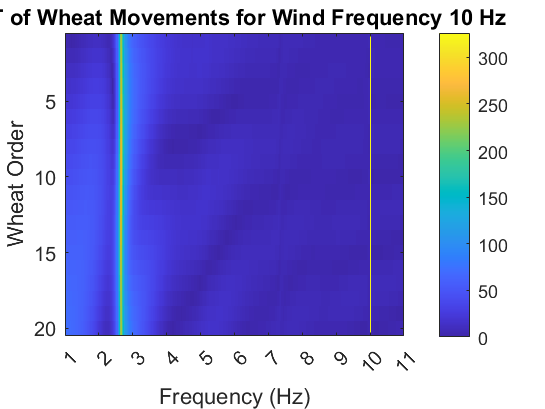

% Clear previous figures
clf

% Create a new figure
fig = figure(1);
set(fig, 'Color', 'w'); % Set background color to white

% wind_freq_order = 50;
wind_freq = wind_frequency_list(wind_freq_order);
natural_freq = 16/(2*pi);
twice_natural_freq = 2 * natural_freq;

% Calculate the frequency axis for FFT
N = length(result(wind_freq_order).y.Time);
f = (0:N-1)/(N*0.001); % Frequency in Hz

% Create an empty matrix to store FFT results
fft_results = zeros(20, length(f));

% Loop over all 20 wheats
for wheat_order = 1:20
    % Perform FFT and plot the magnitude
    y_fft = abs(fft(squeeze(result(wind_freq_order).y.Data(wheat_order,1,:))));
    y_fft(1) = 0;
    
    % Store the FFT result in the matrix
    fft_results(wheat_order, :) = y_fft;
end

% Create the heatmap
imagesc(f(f <= 11), 1:20, fft_results(:, f <= 11));

% Set the labels
xlabel('Frequency (Hz)');
ylabel('Wheat Order');
title(['FFT of Wheat Movements for Wind Frequency ' num2str(wind_freq) ' Hz']);

% Change the colormap of the figure
colormap('parula');

% Set the x-axis tick labels to show integer values
xticks(1:11);

% Set the axis limits
xlim([1, 11]);

% Add a colorbar
colorbar;


% Mark the natural frequency and twice the natural frequency with arrows
% hold on
% arrow_natural = text(natural_freq, 1, '\leftarrow Natural Frequency', 'HorizontalAlignment', 'right');
% arrow_twice_natural = text(twice_natural_freq, 2, '\leftarrow Twice Natural Frequency', 'HorizontalAlignment', 'right');
% set(arrow_natural, 'Color', 'm', 'FontSize', 12, 'FontWeight', 'bold');
% set(arrow_twice_natural, 'Color', 'y', 'FontSize', 12, 'FontWeight', 'bold');
% hold off


% y_fft = fft(squeeze(out.z.Data(20,1,:)));
% n = length(out.y.Time);
% f = 2*pi*(0:n-1)/out.y.Time(n);
% % k cycles per N samples
% figure(4)
% plot(f(2:end),abs(y_fft(2:end)),"LineWidth",3)
% % xlim([-0.5 1.5])
% % ylim([0 4.5e4])
% xlabel('Frequency (rad/s)')
% ylabel('Magnitude')
% title('FFT plot')

% force_freq_order = 30;
% wheat_order = 20;
time_step = 0.001;

for force_freq_order=29:size(force_frequency_list,2)
    for wheat_order=1:20
        y_fft = fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:)));
        N = length(result(force_freq_order).y.Time);
        % f = 2*pi*(0:N-1)/result(force_freq_order).y.Time(N);
        f = 2*pi*(0:N-1)/(N*time_step);
        % k cycles per N samples
        fig = figure(1);
        plot(f(2:end),abs(y_fft(2:end)),"LineWidth",3)
        % xlim([-0.5 1.5])
        % ylim([0 4.5e4])
        xlabel('Frequency (rad/s)')
        ylabel('Magnitude')
        title(['FFT plot with'' force freq=' num2str(force_frequency_list(force_freq_order)) ' wheat order=' num2str(wheat_order)])
        xlim([0 200])
        set(fig, 'PaperPositionMode', 'auto')
        image_name=['force_freq=' num2str(force_frequency_list(force_freq_order)) '_wheat_order=' num2str(wheat_order) '.png'];
        saveas(fig,['wheat_line_analysis_image/' image_name])
        clf(fig)
    end
end

Unrecognized function or variable 'force_frequency_list'.

time_step = 0.001;

for force_freq_order=12:size(force_frequency_list,2)
    N = length(result(force_freq_order).y.Time);
    sum_fft = zeros([N 1]);
    for wheat_order=1:20
        y_fft = abs(fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:))));
        sum_fft = sum_fft + y_fft;           
    end
    % f = 2*pi*(0:N-1)/result(force_freq_order).y.Time(N); 
    f = 2*pi*(0:N-1)/(N*time_step);
    fig = figure(1);
    plot(f(2:end),y_fft(2:end),"LineWidth",2)
    % xlim([-0.5 1.5])
    % ylim([0 4.5e4])
    xlabel('Frequency (rad/s)')
    ylabel('Magnitude')
    title(['FFT plot with'' force freq=' num2str(force_frequency_list(force_freq_order)) ' all wheats'])
    xlim([0 200])
    set(fig, 'PaperPositionMode', 'auto')
    image_name=['force_freq=' num2str(force_frequency_list(force_freq_order)) '.png'];
    saveas(fig,['wheat_line_analysis_image/' image_name])
    clf(fig)
end

% force_freq_order = 30;
% wheat_order = 3;
wheat_number = 20;
force_number = size(force_frequency_list,2);
time_step = 0.001;

omega = 16;
omega2 = 2*omega;

N = length(result(1).y.Time);
f = 2*pi*(0:N-1)/(N*time_step);
% Find the difference between the target number and each number in the list
diffList_omega = abs(f - omega);
diffList_omega2 = abs(f - omega2);

% Find the index of the smallest difference
[~, omega_index] = min(diffList_omega);
[~, omega2_index] = min(diffList_omega2);

amp_omega_list = zeros([wheat_number,force_number]);
amp_omega2_list = zeros([wheat_number,force_number]);
amp_wind_freq_list = zeros([wheat_number,force_number]);

for force_freq_order=1:force_number
    wind_freq = force_frequency_list(force_freq_order);
    diffList_wind_freq = abs(f - wind_freq);
    [~, wind_freq_index] = min(diffList_wind_freq);
    
    for wheat_order =  1:wheat_number
        y_fft = fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:)));
        
        amp_omega_list(wheat_order,force_freq_order) = abs(y_fft(omega_index));
        amp_omega2_list(wheat_order,force_freq_order) = abs(y_fft(omega2_index));
        
        amp_wind_freq_list(wheat_order,force_freq_order) = abs(y_fft(wind_freq_index));
    end
end

fig = figure(1);
plot(force_frequency_list, amp_omega_list,"LineWidth",2,'DisplayName','omega')
hold on
plot(force_frequency_list, amp_omega2_list,"LineWidth",2,'DisplayName','2*omega')
% xlim([-0.5 1.5])
% ylim([0 4.5e4])
xlabel('Wind Frequency (rad/s)')
ylabel('Magnitude')
title(['FFT plot with' ' wheat order=' num2str(wheat_order)])
% xlim([0 200])
legend()
set(fig, 'PaperPositionMode', 'auto')
image_name=['wheat_order=' num2str(wheat_order) '.png'];
% saveas(fig,['wheat_line_analysis_image/' image_name])
% clf(fig)

fig2 = figure(2);

for wheat_order =  1:wheat_number
    plot(force_frequency_list, amp_omega_list(wheat_order,:),"LineWidth",2,'DisplayName',int2str(wheat_order))
    hold on
end

xlabel('Wind Frequency (rad/s)')
ylabel('Magnitude')
title(['FFT plot with omega=16'])

% plot(force_frequency_list, amp_omega2_list,"LineWidth",2,'DisplayName','2*omega')
% xlim([-0.5 1.5])
% ylim([0 4.5e4])

% xlim([0 200])
legend()
set(fig, 'PaperPositionMode', 'auto')
image_name=['Freq=omega 16' '.png'];
% saveas(fig,['wheat_line_analysis_image/' image_name])
% clf(fig)

% Generate the 2D image
figure;
imagesc(amp_omega_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at Wheat Natural Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

% Generate the 2D image
figure;
imagesc(amp_omega2_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at 2 times Wheat Natural Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

% Generate the 2D image
figure;
imagesc(amp_wind_freq_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at Wind Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

xline(force_frequency_list(force_freq_order));
xline(15);

x = out.x.Time;
y = squeeze(out.x.Data(20,1,:));

Ts = 0.001;
fs = 1/Ts;
n = length(x);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
